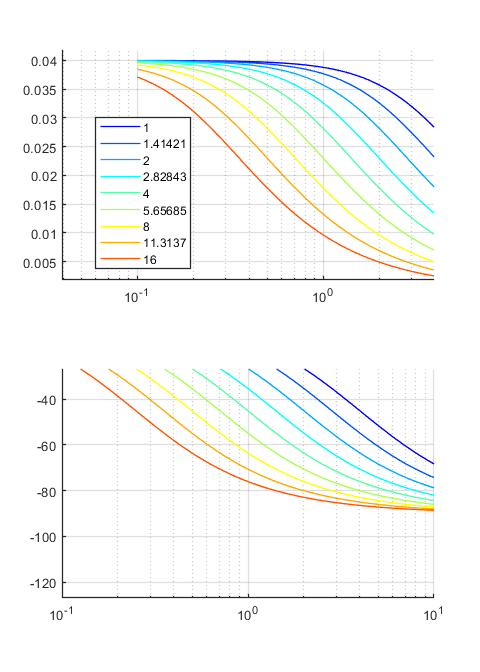

clear ; close all ; clc

I = 1;
C = 25;
K = 1;

varI = 2.^(0:0.5:4);
n_var = length(varI);

fig = figure (1) ; clf
set(fig, 'Color', 'w', 'Units', 'inches', 'Position', [3 3 5 7])
ax(1) = subplot(2,1,1); cla
ax(2) = subplot(2,1,2); cla
set(ax, 'XScale', 'log')
% set(ax, 'YScale', 'log')
set(ax, 'LineWidth', 1, 'XGrid', 'on', 'YGrid', 'on')
fcalc = logspace(-1, 1, 200);
wcalc = fcalc * 2*pi;
cc = jet(n_var);
for n = 1:n_var
    sys = tf(1, [(I*varI(n)) C]);
    [gain, phase, wv] = bode(sys, wcalc);
    gain = squeeze(gain);
    phase = squeeze(phase);
    fv = wv ./ (2*pi);
    subplot(2,1,1) ; hold on
        h.gain(n) = plot(fv, gain, 'LineWidth', 1, 'Color', cc(n,:));
        
    subplot(2,1,2) ; hold on
        h.phase(n) =plot(fv, phase, 'LineWidth', 1, 'Color', cc(n,:));
end
leg = legend(h.gain, string(varI));
leg.Position = [0.2    0.6    0.1979    0.2262];